# STEADY ADVECTION-DIFFUSION PROBLEM

## Oriol CHANDRE VILA

## ISAE-SUPAERO, June 2018

Method of snapshots for Greedy approach. Based on *CME 345: Model Reduction* course of prof. David Amsallem (Stanford University).

clear all; close all; clc;
warning('off')

## Initializing the problem

Firstly, the problem's domain is defined. Also the data necessary to give to the problem its physical sense.

% Variables
global Nx Ny Lx Ly dx dy x y Ti Tleft;
Nx = 61;
Ny = 61;
Lx = 1;
Ly = 1;
dx = Lx/(Nx-1);
dy = Ly/(Ny-1);
x = 0:dx:Lx;
y = 0:dy:Ly;
Ti = 300;
Tleft = 950;

Secondly, the limit values of the three parameters are defined:

- **u [p(1,:)]          **     advection speed in the x-direction

- **kappa [p(2,:)]       **diffusivity coefficient

- **ybar [p(3,:)]          **parameterizing the Dirichlet boundary condition    

pMin = [0;0.0005;0.4];
pMax = [0.5;0.025;0.6];

## Part I: computing the comparison points

In order to judge our POD solution, it is necessary to compute some referencial points.

nPointsPerDirection = 10;
uComp = linspace(pMin(1),pMax(1),nPointsPerDirection);
kappaComp = linspace(pMin(2),pMax(2),nPointsPerDirection);
ybarcomp = linspace(pMin(3),pMax(3),nPointsPerDirection);
nComp = nPointsPerDirection^3;
wComp = zeros((Nx-2)*(Ny-2),nComp);
pComp = zeros(3,nComp);
count = 0;
tic
for ip=1:nPointsPerDirection
  for jp=1:nPointsPerDirection
     for kp=1:nPointsPerDirection
       count = count+1;
       pComp(:,count) = [uComp(ip);kappaComp(jp);ybarcomp(kp)];
       [A,b,TleftBC] = buildAdvectionDiffusionOperators...
           (pComp(1,count),pComp(2,count),pComp(3,count));
       % steady state resolution - inversion K*q=F A*wcomp=b
       wComp(:,count) = A\(b);
     end
  end
end
disp('Time needed for a Full-Case Solution (s)')

Time needed for a Full-Case Solution (s)


t_FullCase = toc

t_FullCase = 10.0139

## **Part II: computing ROM**

Now, the POD solution is created using a Greedy+POD algorithm. It is solved 20 times in order to get the average values of the interesting parameters.

nTest = 20;
[eMax_POD, eAvg_POD, t_POD, wPOD,V]=POD(nTest,wComp, pComp,...
    nComp,pMin,pMax,nPointsPerDirection, 291);
disp('Average errors (%)')

Average errors (%)


eMax_POD = eMax_POD*100

eMax_POD = 6.9322

eAvg_POD = eAvg_POD*100

eAvg_POD = 0.9454

disp('Average time needed (s)')

Average time needed (s)


t_POD_Avg = mean(t_POD)

t_POD_Avg = 1.4711

## Part III: post-process

Here, different graphs are presented. First of all, the temperature fields of the interesting solution is computed.

T_Comp = zeros(Ny-2,Nx-2); T_POD = zeros(Ny-2,Nx-2); 
T_Comp(:) = wComp(:,291);
T_Comp = [TleftBC,T_Comp];
T_POD(:) = wPOD(:,1);
T_POD = [TleftBC,T_POD];

Then, we are now able to compute the Temperature field solution of our problem: $u_1 =0\ldotp 11\text{ }\frac{m}{s}\text{ }$, $\kappa =0\ldotp 025\text{ }\frac{m^2 }{s}$ and $\overline{y} =0\ldotp 4$.

Firstly, the reference field:

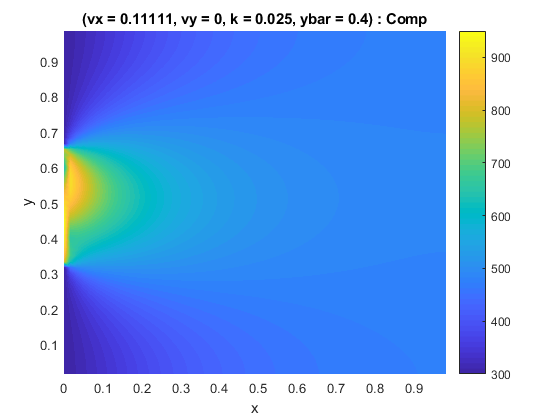

figInt = 0;
% Comp Plot
figInt = figInt + 1;
figure(figInt);
surface(x(1:end-1),y(2:end-1),T_Comp,'EdgeColor','none',...
    'facecolor','interp','FaceLighting','phong');
axis tight
c = colorbar;
h = findobj(gcf,'type','line');
set(h,'linewidth',2);
set(h,'MarkerSize',10);
interp = 'none';
titleStr = ['(vx = ',num2str(pComp(1,291)),', vy = ',num2str(0),...
    ', k = ',num2str(pComp(2,291)),', ybar = ',num2str(pComp(3,291)),')'...
    ,' : Comp'];
title(titleStr,'Interpreter',interp,'fontweight','b');
xlabel('x','Interpreter',interp,'fontweight','b');
ylabel('y','Interpreter',interp,'fontweight','b');
gca = findall(gcf,'type','axes','visible','on');
set(gca,'FontSize',10);

Secondly, the POD field:

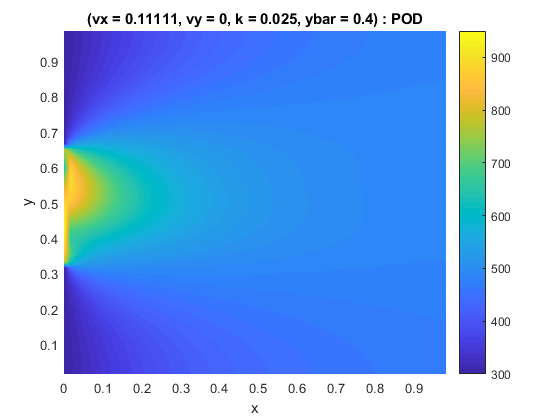

% POD Plot
figInt = figInt + 1;
figure(figInt);
surface(x(1:end-1),y(2:end-1),T_POD,'EdgeColor','none',...
    'facecolor','interp','FaceLighting','phong');
axis tight
c = colorbar;
h = findobj(gcf,'type','line');
set(h,'linewidth',2);
set(h,'MarkerSize',10);
interp = 'none';
titleStr = ['(vx = ',num2str(pComp(1,291)),', vy = ',num2str(0),...
    ', k = ',num2str(pComp(2,291)),', ybar = ',num2str(pComp(3,291)),')'...
    ,' : POD'];
title(titleStr,'Interpreter',interp,'fontweight','b');
xlabel('x','Interpreter',interp,'fontweight','b');
ylabel('y','Interpreter',interp,'fontweight','b');
gca = findall(gcf,'type','axes','visible','on');
set(gca,'FontSize',10);

And, finally, the modes of the POD solution are computed:

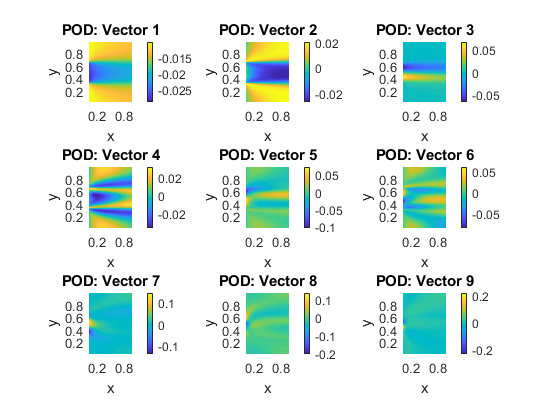

% POD MODES PLOT
POD1 = zeros(Ny-2,Nx-2); POD2 = zeros(Ny-2,Nx-2); POD3 = zeros(Ny-2,Nx-2);
POD4 = zeros(Ny-2,Nx-2); POD5 = zeros(Ny-2,Nx-2); POD6 = zeros(Ny-2,Nx-2);
POD7 = zeros(Ny-2,Nx-2); POD8 = zeros(Ny-2,Nx-2); POD9 = zeros(Ny-2,Nx-2);
POD1(:) = V(:,1); POD2(:) = V(:,2); POD3(:) = V(:,3);
POD4(:) = V(:,4); POD5(:) = V(:,5); POD6(:) = V(:,6);
POD7(:) = V(:,7); POD8(:) = V(:,8); POD9(:) = V(:,9);
figInt = figInt + 1;
figure(figInt);
subplot(3,3,1);
surface(x(2:end-1),y(2:end-1),POD1,'EdgeColor','none',...
    'facecolor','interp','FaceLighting','phong');
axis tight
c = colorbar;
h = findobj(gcf,'type','line');
set(h,'linewidth',2);
set(h,'MarkerSize',10);
interp = 'none';
title('POD: Vector 1','Interpreter',interp,'fontweight','b');
xlabel('x','Interpreter',interp,'fontweight','b');
ylabel('y','Interpreter',interp,'fontweight','b');
gca = findall(gcf,'type','axes','visible','on');
set(gca,'FontSize',10);
subplot(3,3,2);
surface(x(2:end-1),y(2:end-1),POD2,'EdgeColor','none',...
    'facecolor','interp','FaceLighting','phong');
axis tight
c = colorbar;
h = findobj(gcf,'type','line');
set(h,'linewidth',2);
set(h,'MarkerSize',10);
interp = 'none';
title('POD: Vector 2','Interpreter',interp,'fontweight','b');
xlabel('x','Interpreter',interp,'fontweight','b');
ylabel('y','Interpreter',interp,'fontweight','b');
gca = findall(gcf,'type','axes','visible','on');
set(gca,'FontSize',10);
subplot(3,3,3);
surface(x(2:end-1),y(2:end-1),POD3,'EdgeColor','none',...
    'facecolor','interp','FaceLighting','phong');
axis tight
c = colorbar;
h = findobj(gcf,'type','line');
set(h,'linewidth',2);
set(h,'MarkerSize',10);
interp = 'none';
title('POD: Vector 3','Interpreter',interp,'fontweight','b');
xlabel('x','Interpreter',interp,'fontweight','b');
ylabel('y','Interpreter',interp,'fontweight','b');
gca = findall(gcf,'type','axes','visible','on');
set(gca,'FontSize',10);
subplot(3,3,4);
surface(x(2:end-1),y(2:end-1),POD4,'EdgeColor','none',...
    'facecolor','interp','FaceLighting','phong');
axis tight
c = colorbar;
h = findobj(gcf,'type','line');
set(h,'linewidth',2);
set(h,'MarkerSize',10);
interp = 'none';
title('POD: Vector 4','Interpreter',interp,'fontweight','b');
xlabel('x','Interpreter',interp,'fontweight','b');
ylabel('y','Interpreter',interp,'fontweight','b');
gca = findall(gcf,'type','axes','visible','on');
set(gca,'FontSize',10);
subplot(3,3,5);
surface(x(2:end-1),y(2:end-1),POD5,'EdgeColor','none',...
    'facecolor','interp','FaceLighting','phong');
axis tight
c = colorbar;
h = findobj(gcf,'type','line');
set(h,'linewidth',2);
set(h,'MarkerSize',10);
interp = 'none';
title('POD: Vector 5','Interpreter',interp,'fontweight','b');
xlabel('x','Interpreter',interp,'fontweight','b');
ylabel('y','Interpreter',interp,'fontweight','b');
gca = findall(gcf,'type','axes','visible','on');
set(gca,'FontSize',10);
subplot(3,3,6);
surface(x(2:end-1),y(2:end-1),POD6,'EdgeColor','none',...
    'facecolor','interp','FaceLighting','phong');
axis tight
c = colorbar;
h = findobj(gcf,'type','line');
set(h,'linewidth',2);
set(h,'MarkerSize',10);
interp = 'none';
title('POD: Vector 6','Interpreter',interp,'fontweight','b');
xlabel('x','Interpreter',interp,'fontweight','b');
ylabel('y','Interpreter',interp,'fontweight','b');
gca = findall(gcf,'type','axes','visible','on');
set(gca,'FontSize',10);
subplot(3,3,7);
surface(x(2:end-1),y(2:end-1),POD7,'EdgeColor','none',...
    'facecolor','interp','FaceLighting','phong');
axis tight
c = colorbar;
h = findobj(gcf,'type','line');
set(h,'linewidth',2);
set(h,'MarkerSize',10);
interp = 'none';
title('POD: Vector 7','Interpreter',interp,'fontweight','b');
xlabel('x','Interpreter',interp,'fontweight','b');
ylabel('y','Interpreter',interp,'fontweight','b');
gca = findall(gcf,'type','axes','visible','on');
set(gca,'FontSize',10);
subplot(3,3,8);
surface(x(2:end-1),y(2:end-1),POD8,'EdgeColor','none',...
    'facecolor','interp','FaceLighting','phong');
axis tight
c = colorbar;
h = findobj(gcf,'type','line');
set(h,'linewidth',2);
set(h,'MarkerSize',10);
interp = 'none';
title('POD: Vector 8','Interpreter',interp,'fontweight','b');
xlabel('x','Interpreter',interp,'fontweight','b');
ylabel('y','Interpreter',interp,'fontweight','b');
gca = findall(gcf,'type','axes','visible','on');
set(gca,'FontSize',10);
subplot(3,3,9);
surface(x(2:end-1),y(2:end-1),POD9,'EdgeColor','none',...
    'facecolor','interp','FaceLighting','phong');
axis tight
c = colorbar;
h = findobj(gcf,'type','line');
set(h,'linewidth',2);
set(h,'MarkerSize',10);
interp = 'none';
title('POD: Vector 9','Interpreter',interp,'fontweight','b');
xlabel('x','Interpreter',interp,'fontweight','b');
ylabel('y','Interpreter',interp,'fontweight','b');
gca = findall(gcf,'type','axes','visible','on');
set(gca,'FontSize',10);

## Appendices: 

**function *****buildAdvectionDiffusionOperators.m***

function [A,b,TleftBC] = buildAdvectionDiffusionOperators(u,kappa,ybar)

global Nx Ny;

if (u<0)
   disp('Error: u should be positive');
   return;
end


% Dirichlet boundary conditions

[b1,TleftBC] = computeb1(u,kappa,ybar);
b = [b1;zeros((Nx-3)*(Ny-2),1)];

% operators
A2 = computeA2();

A1 = computeA1();
        
A = kappa*A1-u*A2;
end

**function *****buildPrecomputedOperators.m***

function [Ar1,Ar2,Ar3,Ar4,Ar5,Z1,Z2,V1] = buildPrecomputedOperators(V)

global Ny;

A2 = computeA2();

A1 = computeA1();

Y1 = A1*V;
Y2 = A2*V;

Z1 = Y1(1:(Ny-2),:);
Z2 = Y2(1:(Ny-2),:);

Ar1 = Y1'*Y1;
Ar2 = Y1'*Y2 + Y2'*Y1;
Ar3 = Y2'*Y2;
Ar4 = V'*Y1;
Ar5 = V'*Y2;

V1 = V(1:(Ny-2),:);

end

**function***** computeA1.m***

function A1 = computeA1()

global Nx Ny dx dy;

D2x = spdiags([ones(Nx-2,1),-2*ones(Nx-2,1),ones(Nx-2,1)],-1:1,Nx-2,Nx-2);
D2x(Nx-2,Nx-2) = -1;
D2x = 1/dx^2*D2x;

D2y = spdiags([ones(Ny-2,1),-2*ones(Ny-2,1),ones(Ny-2,1)],-1:1,Ny-2,Ny-2);
D2y(Ny-2,Ny-2) = -1;
D2y(1,1) = -1;
D2y = 1/dy^2*D2y;

A1 = kron(D2x,eye(Ny-2)) + kron(eye(Nx-2),D2y);

end

**function***** computeA2.m***

function A2 = computeA2()

global Nx Ny dx;

D1x =  spdiags([-ones(Nx-2,1),ones(Nx-2,1)],-1:0,Nx-2,Nx-2); % upstream
D1x = 1/dx*D1x;

A2 = kron(D1x,eye(Ny-2));

end

**function***** computeb1.m***

function [b1,TleftBC] = computeb1(u,kappa,ybar)

global Ny Ly dx y Ti Tleft;

TleftBC = zeros(Ny-2,1);
b1 = zeros(Ny-2,1);
for i=2:Ny-1
     if (y(i)<Ly/3)
        TleftBC(i-1,1) = Ti;
        b1(i-1,1) = -(u/dx+ kappa/dx^2)*TleftBC(i-1,1);
     elseif (y(i)>2*Ly/3)
        TleftBC(i-1,1) = Ti;
        b1(i-1,1) = -(u/dx+ kappa/dx^2)*TleftBC(i-1,1);
     else
        TleftBC(i-1,1) = Ti+(Tleft-Ti)*(sin(pi*abs(y(i)-ybar)/(1/3))+1)/2;
        b1(i-1,1) = -(u/dx+ kappa/dx^2)*TleftBC(i-1,1);
     end 
end

end

**function***** POD.m***

function [eMax, eAvg, temps, w, V] = POD(nTest,wComp, pComp, nComp,...
    pMin, pMax, nPointsPerDirection, id)

global Nx Ny;

eMax = 0;
eAvg = 0;
temps = zeros(nTest,1);
for iTest=1:nTest
    tic
    nSamples = 10;
    nIterations = nSamples-1;
    nCandidates = 1000;
    pCandidate = pMin*ones(1,nCandidates) + lhsdesign(nCandidates,3)'...
        .*((pMax-pMin)*ones(1,nCandidates));
    % sample 1 point in the middle of the domain
    pMiddle = (pMin+pMax)/2;
    wSamples = zeros((Nx-2)*(Ny-2),nSamples);
    [A,b,~] = buildAdvectionDiffusionOperators(pMiddle(1,1),...
        pMiddle(2,1),pMiddle(3,1));
    wMiddle = A\b;
    wSamples(:,1)= wMiddle;
    [V,~,~] = svd(wSamples,0);

    for iIteration=1:nIterations
      [Ar1,Ar2,Ar3,Ar4,Ar5,Z1,Z2,V1] = buildPrecomputedOperators(V);
      maxError = 0;
      candidateMaxError = 0;
      for iCandidate=1:nCandidates
         % form ROM
         [b1,~] = computeb1(pCandidate(1,iCandidate),...
             pCandidate(2,iCandidate),pCandidate(3,iCandidate));
         Ar = pCandidate(2,iCandidate)*Ar4 - pCandidate(1,iCandidate)*Ar5;
         br = V1'*b1;
         % solve ROM
         q = Ar\br;      
         % compute error indication
         errorIndicator = q'*(pCandidate(2,iCandidate)^2*Ar1-...
             pCandidate(2,iCandidate)*pCandidate(1,iCandidate)*Ar2+...
             pCandidate(1,iCandidate)^2*Ar3)*q-2*(pCandidate(2,iCandidate)...
             *b1'*Z1-pCandidate(1,iCandidate)*b1'*Z2)*q+b1'*b1;
          if (iCandidate==1 || maxError<errorIndicator)
             candidateMaxError = iCandidate;
             maxError = errorIndicator;
          end
       end
       % Solve HDM (High-Dimensional Model)
       [A,b,~] = buildAdvectionDiffusionOperators(...
           pCandidate(1,candidateMaxError),pCandidate(2,candidateMaxError),...
           pCandidate(3,candidateMaxError));
       wSamples(:,iIteration+1) = A\b;
       % Compute ROB
       [V,~,~] = svd(wSamples(:,1:iIteration+1),0);
    end

    % test the ROM of dimension 20 on the comparison points
    k = size(V,2);
    q = zeros(k,nComp);
    error = zeros(nComp,1);
    count = 0;
    for ip=1:nPointsPerDirection
      for jp=1:nPointsPerDirection
         for kp=1:nPointsPerDirection
           count = count+1;  
           [A,b,~] = buildAdvectionDiffusionOperators(pComp(1,count),...
               pComp(2,count),pComp(3,count));
           Ar = V'*A*V;
           br = V'*b;
           % steady state
           q(:,count) = Ar\br;
           wTilde = V*q(:,count);
           error(count,1) = norm(wComp(:,count)-wTilde,2)/...
               norm(wComp(:,count),2);
           if count == id
               w = wTilde;
           end
         end
      end
    end
    eMax = eMax + 1/nTest*max(error);
    eAvg = eAvg + 1/nTest*mean(error);
    temps(iTest) = toc;
end
end